# 串联超前校正

G1=tf(10,[1 0]);
G2=tf(2,[0.2 1]);
H=1;

## 1．计算串联校正装置的传递函数 Gc（s）和校正网络参数。

a=11;%分度系数
T=0.005;%时间常数
Gc=tf([a*T 1],[T a]);
% Gc1=tf(1,2);
% Gc2=tf(2*[0.055 1],[0.005 1]);
% Gc00=series(Gc1,Gc2);
sprintf("校正网络参数a=%g,T=%g",a,T);
display(Gc);

Gc =
 
  0.055 s + 1
  ------------
  0.005 s + 11
 
Continuous-time transfer function.



##  2．画出校正后系统的对数坐标图，并求出校正后系统的ω′c及ν′。

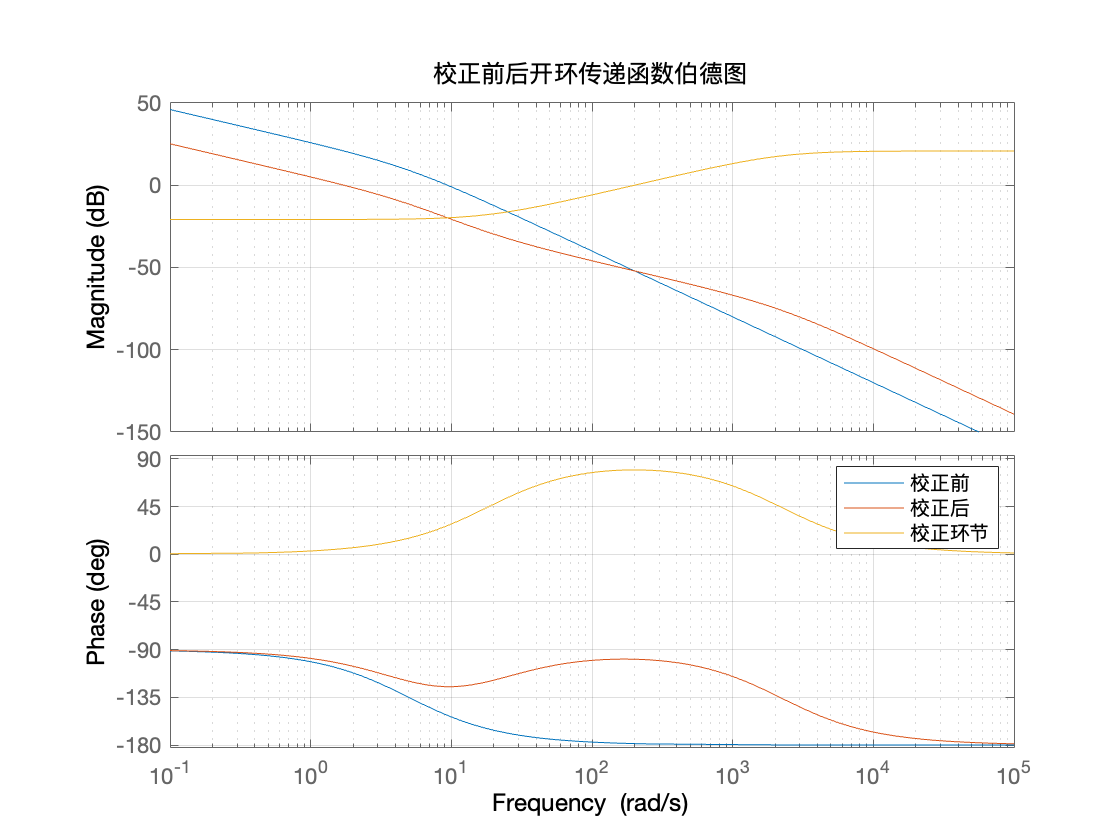

G_ori=series(G1,G2);
G_corr=series(Gc,G_ori);

figure();
bode(G_ori,G_corr,Gc);grid;
legend('校正前','校正后','校正环节');title('校正前后开环传递函数伯德图');

[Gm_ori,Pm_ori] = margin(G_ori);%Gm: gain margin幅值裕度，单位为一 
[Gm_corr,Pm_corr] = margin(G_corr);%Pm: phase margin相角裕度
info1=sprintf("校正前：幅值裕度：%g,相角裕度：%g",Gm_ori,Pm_ori);
info2=sprintf("校正后：幅值裕度：%g,相角裕度：%g",Gm_corr,Pm_corr);
display([info1,info2]);

  1×2 string 数组

    "校正前：幅值裕度：Inf,相角裕度：28.0243"    "校正后：幅值裕度：Inf,相角裕度：76.3307"



## 3．比较校正前后系统的阶跃响应曲线及性能指标，说明校正装置的作用。

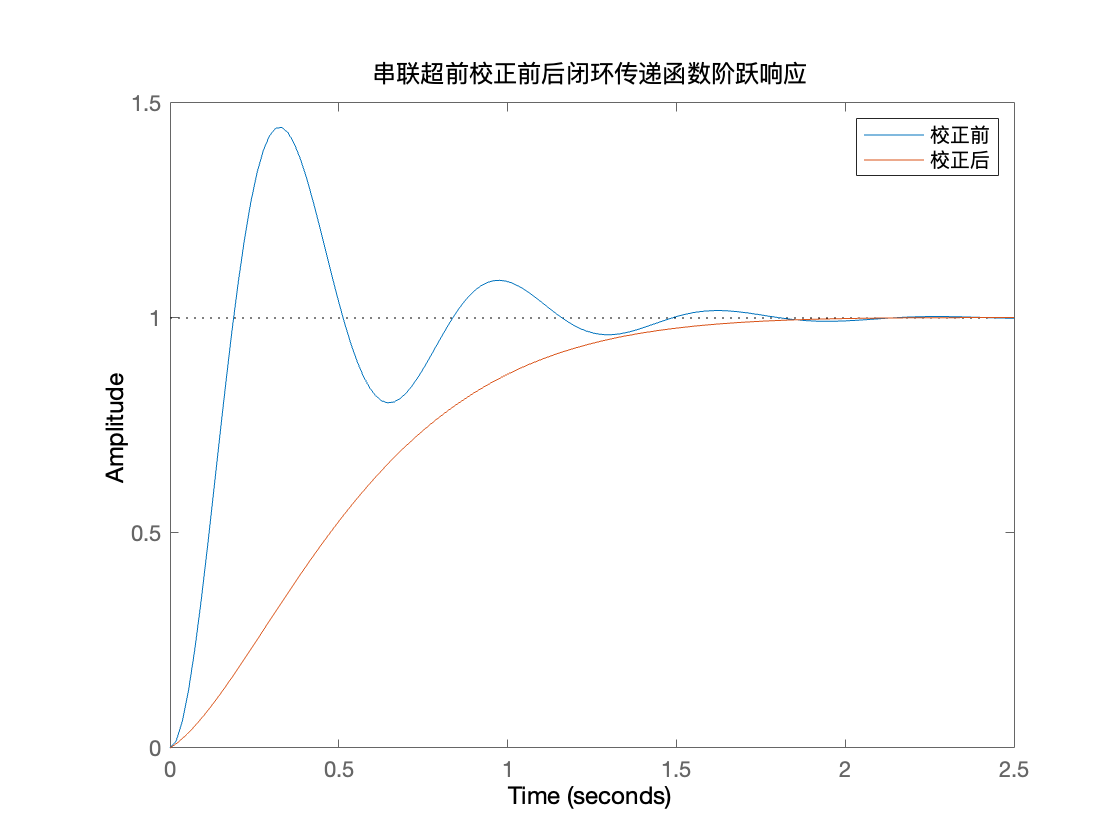

Phi_ori=feedback(G_ori,H);
Phi_corr=feedback(G_corr,H);
figure();
stepplot(Phi_ori,Phi_corr);
legend('校正前','校正后');title('串联超前校正前后闭环传递函数阶跃响应');

info_ori=stepinfo(Phi_ori);
info_corr=stepinfo(Phi_corr);
struct2table([info_ori,info_corr])

ans = 2×8 table
    RiseTime    SettlingTime    SettlingMin    SettlingMax    Overshoot    Undershoot     Peak     PeakTime
    ________    ____________    ___________    ___________    _________    __________    ______    ________

    0.12687        1.4116         0.80273        1.4432         44.323         0         1.4432    0.33157 
     0.9636        1.5402         0.90026         1.001       0.096358         0          1.001      2.463 
